# **Project Proposal**

**1. Title**

Denoising and Enhancement of Brain MRI Images Using DSP Filtering Techniques

**2. Objective **

The objective of this project is to improve the visual quality of brain MRI images by simulating different noise conditions, removing noise, and enhancing structural details using Digital Signal Processing (DSP) techniques in MATLAB. The aim is to enable clearer visualization of anatomical features, supporting improved diagnostic imaging.

**3. Background and Motivation **

Magnetic resonance imaging (MRI) is an important tool for the diagnosis of neurological disorders. However, MRI images are often affected by Gaussian noise, motion artifacts, or acquisition-related distortions that may blur important anatomical structures. Therefore, we can reduce the noise by applying DSP-based filtering and enhancement techniques so that we can preserve critical details while ultimately improving the clarity and interpretability of the images for further analysis or segmentation.

**4. Scope of Work**

- Import and preprocess publicly available brain MRI images.

- Simulate Gaussian and salt-and-pepper noise at varying intensities to evaluate the robustness of filters.

- Apply spatial domain filters (Gaussian, median, and Wiener) to denoise the images.

- Implement frequency domain enhancement techniques using FFT and high-pass filtering.

- Compare and visualize the results of different denoising and enhancement methods.

- Evaluate performance using quantitative metrics (SNR, PSNR) and qualitative visual inspection.

**5. Methodology**

- Using MATLAB and the Image Processing Toolbox.

- Applying Spatial Filters:

- Gaussian filter for soft denoising.

- Median filter for speckle or salt-and-pepper noise.

- Wiener filter for adaptive filtering.

- Apply frequency domain filters using FFT:

- Remove low-frequency background noise.

- Enhance edges using high-frequency emphasis.

- Visualize using `imshowpair`, subplots, and other MATLAB tools.

- Optional: Add synthetic noise to compare the robustness of different methods.

**6. Expected Outcome**

This project will develop a MATLAB-based system that uses digital filtering technology to improve the image quality of brain MRI scans. We will use visual comparisons to show which digital signal processing (DSP) method performs best under different noise conditions. Ultimately, the system will enable clearer visualization of brain structures, revealing the role of preprocessing steps in medical image processing pipelines. This will help us better understand the role of signal processing in medical imaging.

**7. Timeline **

- Week 1: Data collection and preprocessing.

- Week 2: Noise simulation and spatial filtering implementation.

- Week 3: Frequency domain filtering and enhancement.

- Week 4: Performance evaluation, visualization, and report compilation.

**8. Reference**

[1] BrainWeb: Simulated Brain Database. [Online]. Available: [http://brainweb.bic.mni.mcgill.ca/](http://brainweb.bic.mni.mcgill.ca/)

[2] D. MacDonald, *loadminc (File Exchange)*, MathWorks MATLAB Central, 2011. [Online]. Available: [https://www.mathworks.com/matlabcentral/fileexchange/32644-loadminc](https://www.mathworks.com/matlabcentral/fileexchange/32644-loadminc)

[3] A. Gupta and S. Tiwari, "A Review on Image Denoising Techniques," International Research Journal of Engineering and Technology (IRJET), vol. 3, no. 5, pp. 2471–2474, May 2016. [Online]. Available: [https://www.irjet.net/archives/V3/i5/IRJET-V3I554.pdf](https://www.irjet.net/archives/V3/i5/IRJET-V3I554.pdf) 

[4] P. Virtue and M. Lustig, "The empirical effect of Gaussian noise in undersampled MRI reconstruction," Tomography, vol. 3, no. 4, pp. 211–221, Dec. 2017. doi: 10.18383/j.tom.2017.00019

# **Project Report**

**1. Exccutive Summary **

This project utilizes digital signal processing (DSP) technology in MATLAB to enhance the quality of brain MRI images. The publicly available BrainWeb MRI dataset (in .mnc format) was used as input. Gaussian noise and salt-and-pepper noise were added to simulate artifacts encountered in actual imaging. Spatial domain filters (Gaussian filtering, median filtering, Wiener filtering) and frequency domain filtering via the Fast Fourier Transform (FFT) were implemented to reduce noise and enhance structural details.

Quantitative evaluation was performed using peak signal-to-noise ratio (PSNR), and qualitative results were visualized. Experiments showed that Wiener filtering and median filtering were effective for Gaussian noise and salt-and-pepper noise, respectively, while FFT-based filtering achieved edge enhancement and background noise removal.

**2. Materials and Methods**

Dataset

- **BrainWeb MRI dataset** (format: `.mnc`)

- A single 2D slice was extracted from the 3D volume for testing

Noise Simulation

- **Gaussian noise** (mean = 0, variance = 0.01)

- **Salt-and-pepper noise** (density = 0.02)

Filtering Methods

- **Gaussian filter** (spatial smoothing, kernel σ=2)

- **Median filter** (3×3 neighborhood, effective for impulse noise)

- **Wiener filter** (adaptive filtering on 5×5 window)

- **FFT frequency domain filtering**

- Low-pass filtering to suppress high-frequency noise

- High-pass filtering to enhance edges

Evaluation Metrics

- **Qualitative**: visual comparison (before vs after filtering)

- **Quantitative**: PSNR (Peak Signal-to-Noise Ratio, in dB)

**3. Results**

**    Data Analysis& Code: **

clc; clear; close all;

  ** 3.1 Load dataset**

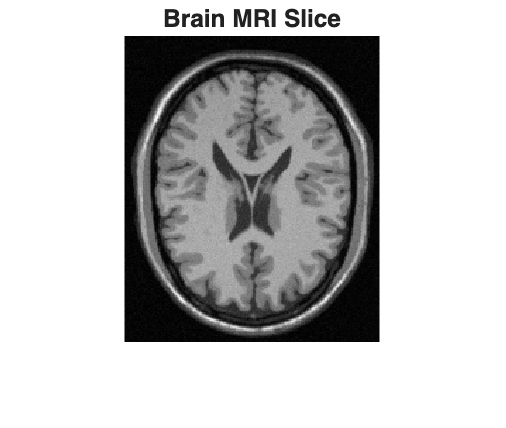

V = loadminc('BrainWeb dataset.mnc');  % read 3D MRI
V = squeeze(V);                        % Take off extra dimension
I = V(:,:,round(size(V,3)/2));         % get ibe MRI slice
I = mat2gray(I);                       
imshow(I,[]); title('Brain MRI Slice');

When I try to load the dataset from BrainWeb and take off extra dimension, we can choose one slice. It showed under:

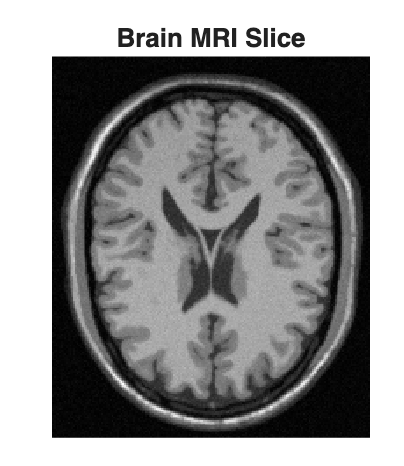

**3.2 Add Synthetic Noise:**

After we get the original Brain MRI Slice, we can try to** add synthetic noise**. **Like Gaussian noise and Salt& Pepper **noise to see what will be happend.

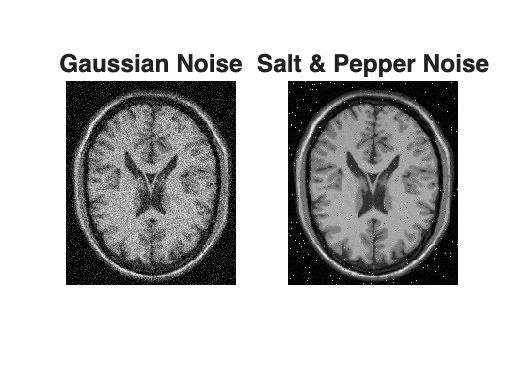

I_gauss = imnoise(I,'gaussian',0,0.01);        % Gaussian noise
I_sp = imnoise(I,'salt & pepper',0.02);        % Salt & Pepper noise

figure;                                        %Plot the figure
subplot(1,2,1); imshow(I_gauss,[]); title("Gaussian Noise"); % Offer the title for Gaussian Noise
subplot(1,2,2); imshow(I_sp,[]); title('Salt & Pepper Noise'); % offer the title ofr Salt and pepper Noise

  We can observe the difference when we apply the Synthetic Noise. 

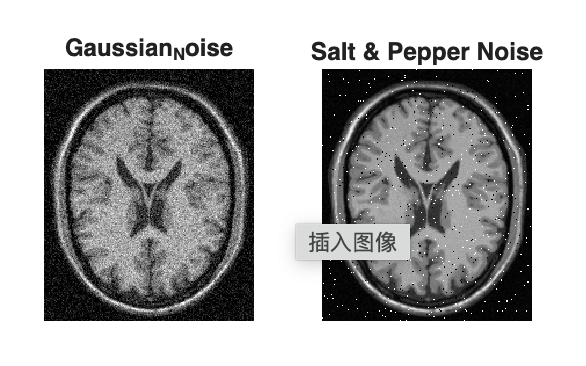

**3.3 Apply Spatial Filters**

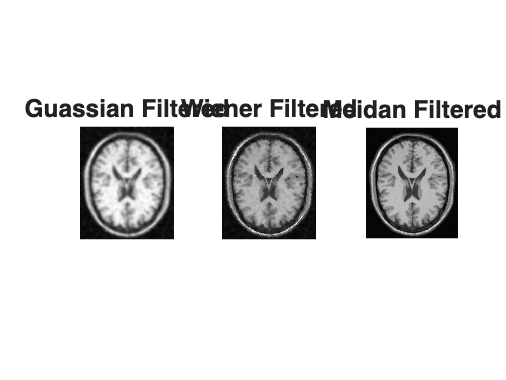

I_gauss_filter = imgaussfilt(I_gauss,2);     % Guassian filter
I_wiener_filter = wiener2(I_gauss, [5 5]);   % Wiener filter
I_median_filter = medfilt2(I_sp, [3 3]);     % Median filter

figure;                                        %plot the figure
subplot(1,3,1); imshow(I_gauss_filter,[]); title('Guassian Filtered'); % Give the title for Gaussian filtered graph
subplot(1,3,2); imshow(I_wiener_filter,[]); title('Wiener Filtered');   % Give the title for Wiener filtered graph
subplot(1,3,3); imshow(I_median_filter,[]); title('Meidan Filtered');    % Give the title for Median filtered graph

As outcome shows, we can identify the three filter difference. 

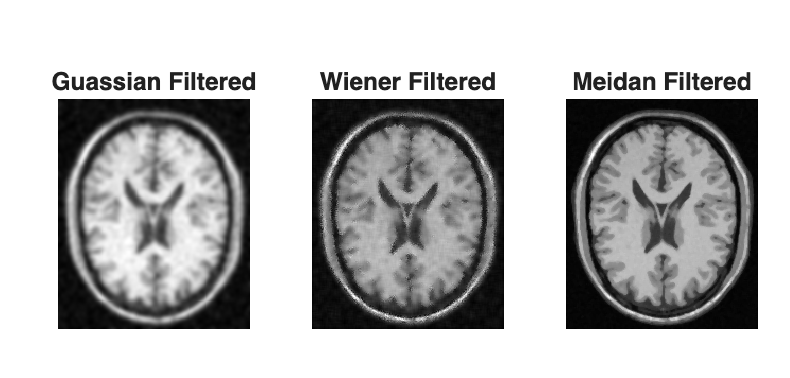

**3.4 FFT filtering( Frequency domain filtering） **

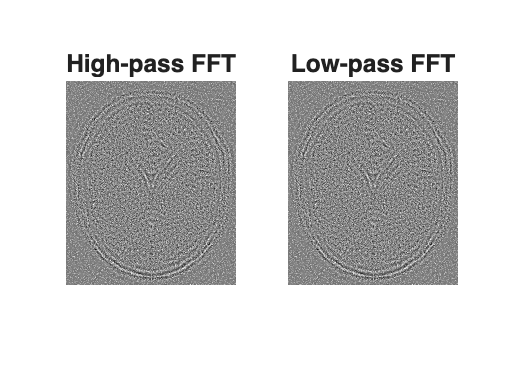

% Compute FFT of noisy image
F = fft2(I_gauss);                          % Take 2D FFT of the noisy image  
F_shift = fftshift(F);                      % Shift zero-frequency component to center

[rows, cols] = size(I);                    % Get image size
[u,v] = meshgrid(1:cols,1:rows);           % Crate grid of coordiates
D0 = 30;                                   % cutoff frequency
D = sqrt((u-cols/2).^2 + (v-rows/2).^2);   % Distance from center
H_low = double(D <= D0);                   % Low-pass 
H_high = double(D > D0);                   % High-pass


F_high = F_shift .* H_high;               % Keep only high frequencies
I_high = real(ifft2(ifftshift(F_high)));  % And inverse FFT
F_low = F_shift .* H_low;                 % Keep only low frequencies
I_low = real(ifft2(ifftshift(F_high)));   % Inverse FFT

figure;                                   % Plot the figure
subplot(1,2,1); imshow(I_high,[]); title("High-pass FFT"); % Give the title for High pass FFT
subplot(1,2,2); imshow(I_low,[]); title('Low-pass FFT');    % Give the title for low-pass FFT

   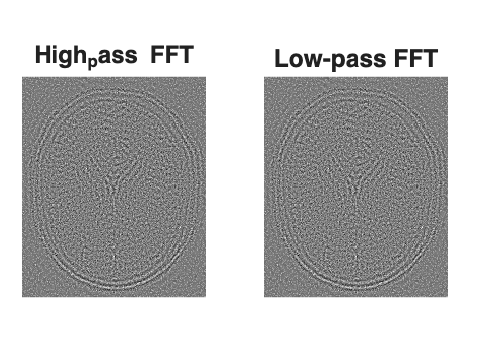

**3.5 PSNR/SNR**

**PSNR (Peak Signal-to-Noise Ratio)** is a common quantitative metric used to measure how close a processed image is to the original (reference) image. **Higher PSNR (in dB)** = processed image is closer to the original = less error. Therefore,we can have PSNR for four filter: FFT, Median, Guassian, Wiener to observe what's the difference between them. And which filter will be better image.

psnr_gauss = psnr(I_gauss_filter,I);      % PSNR Value for Gaussian filter
psnr_med   = psnr(I_median_filter,I);     % PSNR Value for Median filter
psnr_wien  = psnr(I_wiener_filter,I);     % PSNR Value for Wiener filter
psnr_fft   = psnr(I_low,I);               % PSNR Value for FFT filter

fprintf('PSNR (Gaussian Filter): %.2f dB\n', psnr_gauss);

PSNR (Gaussian Filter): 24.16 dB


fprintf('PSNR (Median Filter): %.2f dB\n', psnr_med);

PSNR (Median Filter): 32.85 dB


fprintf('PSNR (Wiener Filter): %.2f dB\n', psnr_wien);

PSNR (Wiener Filter): 26.36 dB


fprintf('PSNR (FFT Low-pass): %.2f dB\n', psnr_fft);

PSNR (FFT Low-pass): 7.52 dB


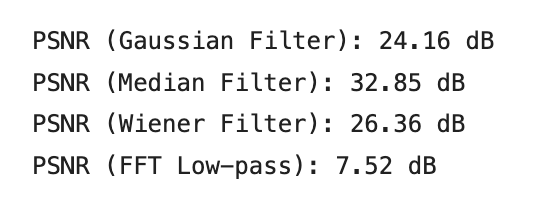

According to the results, we can discover Although the median filter produced the highest PSNR values, it introduced noticeable blurring and loss of fine anatomical details in the MRI images. The Wiener filter, while yielding slightly lower PSNR, preserved structural edges and textures more effectively. This highlights a limitation of PSNR as an evaluation metric: numerical improvements do not always correspond to superior perceptual quality. For medical imaging applications, where structural detail is critical, Wiener filtering is therefore the more suitable approach.

**3.6 Visualization**

 We have already tried drawing different filters, so now we can immediately visualize them to see the differences between them.

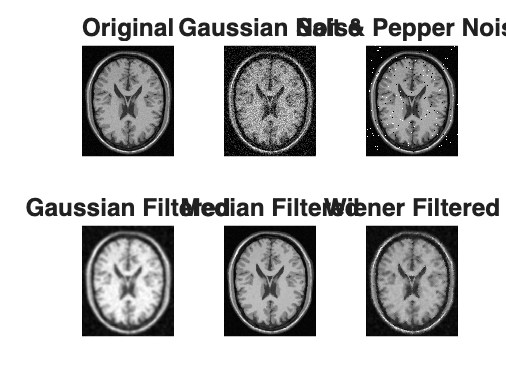

figure;        % plot the figures and visualize them
subplot(2,3,1); imshow(I,[]); title('Original');
subplot(2,3,2); imshow(I_gauss,[]); title('Gaussian Noise');
subplot(2,3,3); imshow(I_sp,[]); title('Salt & Pepper Noise');
subplot(2,3,4); imshow(I_gauss_filter,[]); title('Gaussian Filtered');
subplot(2,3,5); imshow(I_median_filter,[]); title('Median Filtered');
subplot(2,3,6); imshow(I_wiener_filter,[]); title('Wiener Filtered');

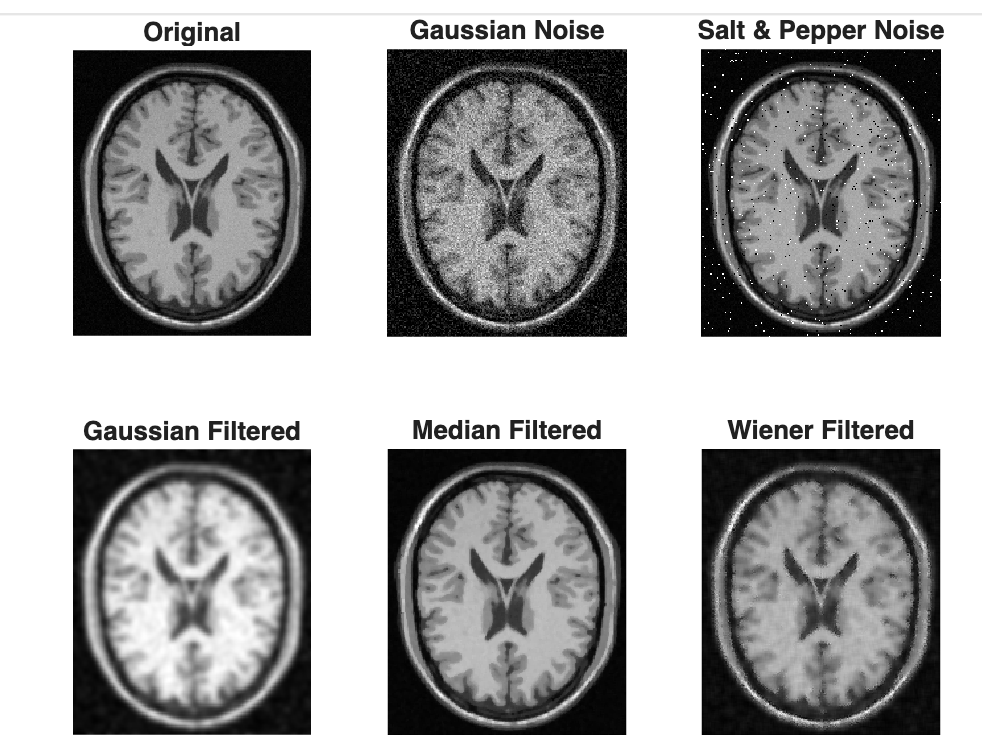

** Outcomes:**

Qualitative observations

- Gaussian filter successfully reduced Gaussian noise, but caused some blurring.

- Median filter effectively removed salt-and-pepper noise while preserving edges.

- Wiener filter performed well on Gaussian noise and achieved the best balance between noise reduction and detail preservation.

- FFT low-pass filtering suppressed high-frequency noise but introduced slight blurring.

- FFT high-pass filtering enhanced edges but also amplified noise.

**4. Conclusion and Challenges Faced**

**  Conclusion:**

    This study demonstrates that digital signal processing techniques can significantly improve MRI image quality by reducing noise and enhancing clarity. Among spatial domain filters, the Wiener filter exhibits the best suppression of Gaussian noise, while the median filter performs exceptionally well in addressing salt-and-pepper noise. Although the Wiener filter does not achieve the highest PSNR, it strikes a good balance between preserving structural details and removing noise from a visual perspective. This suggests that a single quantitative metric (such as PSNR) is insufficient to fully reflect image quality, and qualitative analysis is equally important. Frequency-domain (FFT) filtering can provide effective edge enhancement, but parameters must be chosen carefully to avoid artifacts.

Overall, the study results validate the importance of digital signal processing in medical image preprocessing, aiding in clearer depiction of anatomical structures and enhancing diagnostic potential.

  **Challenges:**

    First, the first small challenge I encountered was determining which dataset was most suitable for me and how to load a large database into MATLAB. Since MATLAB cannot directly read MINC images, we need to download "matlab-minc-tools." Second, regarding the trade-offs of filters—each filter has its advantages but also its drawbacks. For example, excessive noise, blurring, and lack of clarity. Therefore, we should learn how to analyze and distinguish the characteristics of different filters. 

Third, evaluation metrics—while PSNR provides numerical results, there is a discrepancy between the initial visual display of the data and visual perception. For instance, our data may have a high PSNR value, but this does not necessarily mean the filter is better or more accurate. This also highlights the necessity of combining qualitative and quantitative evaluations.

**5. References**

[1] BrainWeb: Simulated Brain Database. [Online]. Available: [http://brainweb.bic.mni.mcgill.ca/](http://brainweb.bic.mni.mcgill.ca/)

[2] MathWorks, *Image Processing Toolbox Documentation*, Natick, MA, USA: MathWorks, 2023. [Online]. Available: [https://www.mathworks.com/help/images/](https://www.mathworks.com/help/images/) 

[3] D. MacDonald, *loadminc (File Exchange)*, MathWorks MATLAB Central, 2011. [Online]. Available: [https://www.mathworks.com/matlabcentral/fileexchange/32644-loadminc](https://www.mathworks.com/matlabcentral/fileexchange/32644-loadminc)

[4] A. Gupta and S. Tiwari, "A Review on Image Denoising Techniques," International Research Journal of Engineering and Technology (IRJET), vol. 3, no. 5, pp. 2471–2474, May 2016. [Online]. Available: [https://www.irjet.net/archives/V3/i5/IRJET-V3I554.pdf](https://www.irjet.net/archives/V3/i5/IRJET-V3I554.pdf) 

[5] P. Virtue and M. Lustig, "The empirical effect of Gaussian noise in undersampled MRI reconstruction," Tomography, vol. 3, no. 4, pp. 211–221, Dec. 2017. doi: 10.18383/j.tom.2017.00019